A0A = [-4 -2 0 2 4 6 8 10 12 14 16 18 20]

A0A =     -4    -2     0     2     4     6     8    10    12    14    16    18    20


A0Ay = cosd(A0A);
A0Ax = sind(A0A);
V20 = 20;
V0 = 0;
V24 = 24.5;
V27 = 27.6;
p = 1.225;                             %density of air kg/m3
c1= 0.087;
c2= 0.071;
c3= 0.064;
%wind span for wing  in metres 
Ch1= (0.18*0.087);                        %wing area for wing  in metres 
Ch2= (0.220*0.071);
Ch3= (0.250*0.064); 
Chords = [c1 c2 c3 c3 c2]

Chords =     0.0870    0.0710    0.0640    0.0640    0.0710


ar1 = (0.18^2)/Ch1                            %wing 180x87 aspect ratio 

ar1 = 2.0690

ar2 = (0.22^2)/Ch2                            %wing  aspect ratio 

ar2 = 3.0986

ar3 = (0.25^2)/Ch3                            %wing  aspect ratio 

ar3 = 3.9063


% wing 180x87 with flow 20ms wing
filename1 = sprintf( 'wing180x87withflow20ms.xlsx', j) ;

nf1 = xlsread( filename1,'','C:C' ); 
af1 = xlsread( filename1,'','D:D' ); 
m1 = xlsread( filename1,'','E:E' ); 

Nf1 = (nf1(1:20:end,:))';
Af1 = (af1(1:20:end,:))';
M1 = (m1(1:20:end,:)*0.01)';
D1 = (Af1.*A0Ay) + (Af1.*A0Ax);
L1 = (Nf1.*A0Ay) - (Nf1.*A0Ax);
Cd1 = (2*Af1)./(p*(V20.^2)*Ch1);                      % profile drag 
Cl1 = (2*Nf1)./(p*(V20.^2)*Ch1);                      % lift coefficient from normal force computation

Cdi1 =  ((Cl1.^2) / (pi * ar1 ) )                        %induced drag 

Cdi1 =     0.0001    0.0013    0.0065    0.0165    0.0290    0.0471    0.0606    0.0979    0.1273    0.1492    0.1790    0.1884    0.2215


CD1 = Cd1 + Cdi1                                        % total drag coefficient 

CD1 =     0.0191    0.0401    0.0608    0.0892    0.1083    0.1313    0.1432    0.1787    0.2039    0.2203    0.2333    0.2338    0.2484


% wing180x87withoutflow wing
filename2 = sprintf( 'wing180x87withoutflow.xlsx', i ) ;
vel2 = xlsread( filename2,'','A:A' );
nf2 = xlsread( filename2,'','C:C' ); 
af2 = xlsread( filename2,'','D:D' ); 
m2 = xlsread( filename2,'','E:E' ); 
Vel2 = (vel2(1:260:end,:))';
Nf2 = (nf2(1:20:end,:))';
Af2 = (af2(1:20:end,:))';
M2 = (m2(1:20:end,:)*0.01)';
D2 = (Af2.*A0Ay) + (Af2.*A0Ax);
L2 = (Nf2.*A0Ay) - (Nf2.*A0Ax);
Cd2 = (2*Af2)./(p*(Vel2.^2)*Ch1);                      % profile drag 
Cl2 = (2*Nf2)./(p*(Vel2.^2)*Ch1);                      % lift coefficient from normal force computation

Cdi2 =  ((Cl2.^2) / (pi * 0.85*ar1 ) )                        %induced drag 

Cdi2 =     0.0013    0.1935    0.0013    0.1935    0.1626    0.0215    0.2634    0.2271    0.5926    0.3023    1.1301    2.3703    4.3658


CD2 = Cd2 + Cdi2

CD2 =    -1.1188    5.4494   10.9439   16.3920   22.2201   27.3349   32.4019   38.3108   44.2768   48.8978   54.2922   61.2191   68.8151


% wing 220x71 with flow 20ms wing
filename3 = sprintf( 'wing220x71mmwithflow20ms.xlsx', i ) ;

nf3 = xlsread( filename3,'','C:C' ); 
af3 = xlsread( filename3,'','D:D' ); 
m3 = xlsread( filename3,'','E:E' ); 

Nf3 = (nf3(1:20:end,:))';
Af3 = (af3(1:20:end,:))';
M3 = (m3(1:20:end,:)*0.01)';
D3 = (Af3.*A0Ay) + (Af3.*A0Ax);
L3 = (Nf3.*A0Ay) - (Nf3.*A0Ax);
Cd3 = (2*Af3)./(p*(V20.^2)*Ch2);                      % profile drag 
Cl3 = (2*Nf3)./(p*(V20.^2)*Ch2);                      % lift coefficient from normal force computation
Cdi3 =  ((Cl3.^2) / (pi * 0.85*ar2 ) )                        %induced drag 

Cdi3 =     0.0017    0.0007    0.0080    0.0188    0.0348    0.0508    0.0761    0.0923    0.1261    0.1574    0.1817    0.1875    0.0847


CD3 = Cd3 + Cdi3 

CD3 =     0.0278    0.0459    0.0712    0.0878    0.1119    0.1237    0.1432    0.1540    0.1742    0.1799    0.1856    0.1847    0.3222



% wing 220x17 without flow  wing
filename4 = sprintf( 'wing220x71withoutflow.xlsx', i ) ;
vel4 = xlsread( filename4,'','A:A' );
nf4 = xlsread( filename4,'','C:C' ); 
af4 = xlsread( filename4,'','D:D' ); 
m4 = xlsread( filename4,'','E:E' ); 
Vel4 = (vel4(1:260:end,:))';
Nf4 = (nf4(1:20:end,:))';
Af4 = (af4(1:20:end,:))';
M4 = (m4(1:20:end,:)*0.01)';
D4 = (Af4.*A0Ay) + (Af4.*A0Ax);
L4 = (Nf4.*A0Ay) - (Nf4.*A0Ax);
Cd4 = (2*Af4)./(p*(Vel4.^2)*Ch2);                      % profile drag 
Cl4 = (2*Nf4)./(p*(Vel4.^2)*Ch2); 
Cdi4 =  ((Cl4.^2) / (pi *0.85* ar2 ) )                        %induced drag 

Cdi4 =    Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf


CD4 = Cd4 + Cdi4 

CD4 =    NaN   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf



% wing 250x64 with flow 20ms wing
filename5 = sprintf( 'wing250x64withflow 20ms.xlsx', i ) ;

nf5 = xlsread( filename5,'','C:C' ); 
af5 = xlsread( filename5,'','D:D' ); 
m5 = xlsread( filename5,'','E:E' ); 

Nf5 = (nf5(1:20:end,:))';
Af5 = (af5(1:20:end,:))';
M5 = (m5(1:20:end,:)*0.01)';
D5 = (Af5.*A0Ay) + (Af5.*A0Ax);
L5 = (Nf5.*A0Ay) - (Nf5.*A0Ax);
Cd5 = (2*Af5)./(p*(V20.^2)*Ch3);                      % profile drag 
Cl5 = (2*Nf5)./(p*(V20.^2)*Ch3);
Cdi5 =  ((Cl5.^2) / (pi *0.85* ar3 ) )                        %induced drag 

Cdi5 =     0.0012    0.0005    0.0074    0.0165    0.0321    0.0537    0.0744    0.0996    0.1177    0.0501    0.0581    0.0663    0.0625


CD5 = Cd5 + Cdi5 

CD5 =     0.0249    0.0443    0.0655    0.0826    0.1003    0.1132    0.1239    0.1338    0.1368    0.2233    0.2535    0.2834    0.2928




% wing 250x64 with flow 27.6ms wing
filename7 = sprintf( 'wing250x64withflow27.6ms.xlsx', i ) ;

nf7 = xlsread( filename7,'','C:C' ); 
af7 = xlsread( filename7,'','D:D' ); 
m7 = xlsread( filename7,'','E:E' ); 

Nf7 = (nf7(1:20:end,:))';
Af7 = (af7(1:20:end,:))';
M7 = (m7(1:20:end,:)*0.01)';
D7 = (Af7.*A0Ay) + (Af7.*A0Ax);
L7 = (Nf7.*A0Ay) - (Nf7.*A0Ax);
Cd7 = (2*Af7)./(p*(V20.^2)*Ch3);                      % profile drag 
Cl7 = (2*Nf7)./(p*(V20.^2)*Ch3);
Cdi7 =  ((Cl7.^2) / (pi * 0.85*ar3 ) )                        %induced drag 

Cdi7 =     0.0008    0.0055    0.0272    0.0691    0.1239    0.1869    0.2788    0.3554    0.4467    0.5167    0.3210    0.2250    0.2379


CD7 = Cd7 + Cdi7 

CD7 =     0.0472    0.0743    0.1055    0.1530    0.1933    0.2325    0.2816    0.3116    0.3442    0.3716    0.4233    0.4743    0.5014


% wing 220x71 with flow 24.5ms wing
filename8 = sprintf( 'wing220x71withflow24.5ms.xlsx', i ) ;


nf8 = xlsread( filename8,'','C:C' ); 
af8 = xlsread( filename8,'','D:D' ); 
m8 = xlsread( filename8,'','E:E' ); 

Nf8 = (nf8(1:20:end,:))';
Af8 = (af8(1:20:end,:))';
M8 = (m8(1:20:end,:)*0.01)';
D8 = (Af8.*A0Ay) + (Af8.*A0Ax);
L8 = (Nf8.*A0Ay) - (Nf8.*A0Ax);
Cd8 = (2*Af8)./(p*(V20.^2)*Ch2);                      % profile drag 
Cl8 = (2*Nf8)./(p*(V20.^2)*Ch2);
Cdi8 =  ((Cl8.^2) / (pi *0.85* ar2 ) )                        %induced drag 

Cdi8 =     0.0012    0.0030    0.0166    0.0445    0.0771    0.1195    0.1681    0.2355    0.3191    0.3667    0.4023    0.4376    0.1758


CD8 = Cd8 + Cdi8 

CD8 =     0.0373    0.0670    0.0934    0.1289    0.1592    0.1887    0.2267    0.2658    0.3123    0.3259    0.3296    0.3349    0.4368





AF = [Af1;  Af3;  Af5;  Af8];
NF = [Nf1; Nf3 ; Nf5 ;Nf7; Nf8];
M = [M1 ;M3 ; M5 ;M7; M8]

M =    -0.0277   -0.0156   -0.0001    0.0128    0.0261    0.0395    0.0490    0.0663    0.0779    0.0859    0.0964    0.1012    0.1115
   -0.0288   -0.0116    0.0079    0.0229    0.0399    0.0535    0.0701    0.0795    0.0960    0.1091    0.1190    0.1225    0.0599
   -0.0280   -0.0108    0.0103    0.0272    0.0461    0.0646    0.0800    0.0963    0.1068    0.0553    0.0588    0.0622    0.0619
   -0.0471   -0.0110    0.0245    0.0589    0.0927    0.1227    0.1569    0.1822    0.2084    0.2268    0.1573    0.1146    0.1186
   -0.0404   -0.0138    0.0108    0.0358    0.0585    0.0807    0.1014    0.1243    0.1479    0.1631    0.1747    0.1825    0.0826


CH = [Ch1 Ch2 Ch3 Ch3 Ch2]

CH =     0.0157    0.0156    0.0160    0.0160    0.0156




Ve = [V20  V20  V20  V27 V24]

Ve =    20.0000   20.0000   20.0000   27.6000   24.5000


mref1 = (M1 - ((0.028 + 0 )* Nf1) )

mref1 =    -0.0256   -0.0255   -0.0222   -0.0224   -0.0206   -0.0200   -0.0184   -0.0194   -0.0198   -0.0199   -0.0195   -0.0177   -0.0174


mref2 = (M3 - ((0.028 + 0 )* Nf3) )

mref2 =    -0.0163   -0.0195   -0.0196   -0.0194   -0.0176   -0.0160   -0.0149   -0.0142   -0.0134   -0.0132   -0.0124   -0.0110   -0.0298


mref3 = (M5 - ((0.028 + 0 )* Nf5) )

mref3 =    -0.0159   -0.0184   -0.0202   -0.0183   -0.0174   -0.0175   -0.0167   -0.0156   -0.0148   -0.0241   -0.0266   -0.0291   -0.0267


mref4 = (M7 - ((0.028 + 0 )* Nf7) )

mref4 =    -0.0371   -0.0372   -0.0340   -0.0342   -0.0321   -0.0305   -0.0303   -0.0292   -0.0285   -0.0280   -0.0436   -0.0536   -0.0543


mref5 = (M8 - ((0.028 + 0 )* Nf8) )

mref5 =    -0.0297   -0.0306   -0.0289   -0.0291   -0.0271   -0.0258   -0.0250   -0.0253   -0.0262   -0.0235   -0.0208   -0.0214   -0.0466


CM1 = (2*mref1)./ (p *V20^2 * 0.087.*Ch1)

CM1 =    -0.0768   -0.0763   -0.0666   -0.0671   -0.0617   -0.0598   -0.0550   -0.0580   -0.0593   -0.0597   -0.0583   -0.0531   -0.0521


CM2 = (2*mref2 )./ (p *V20^2 * 0.071*Ch2)

CM2 =    -0.0600   -0.0717   -0.0723   -0.0713   -0.0646   -0.0588   -0.0549   -0.0522   -0.0494   -0.0485   -0.0457   -0.0403   -0.1097


CM3 = (2*mref3 )./ (p *V20^2 * 0.064*Ch3)

CM3 =    -0.0634   -0.0732   -0.0805   -0.0731   -0.0695   -0.0699   -0.0665   -0.0621   -0.0589   -0.0960   -0.1060   -0.1161   -0.1065


CM4 = (2*mref4 )./ (p *V27^2 * 0.064*Ch3)

CM4 =    -0.0776   -0.0778   -0.0711   -0.0716   -0.0672   -0.0638   -0.0634   -0.0611   -0.0597   -0.0586   -0.0912   -0.1121   -0.1136


CM5 = (2*mref5 )./ (p *V24^2 * 0.071*Ch2)

CM5 =    -0.0728   -0.0751   -0.0708   -0.0715   -0.0665   -0.0633   -0.0613   -0.0621   -0.0643   -0.0577   -0.0509   -0.0524   -0.1144


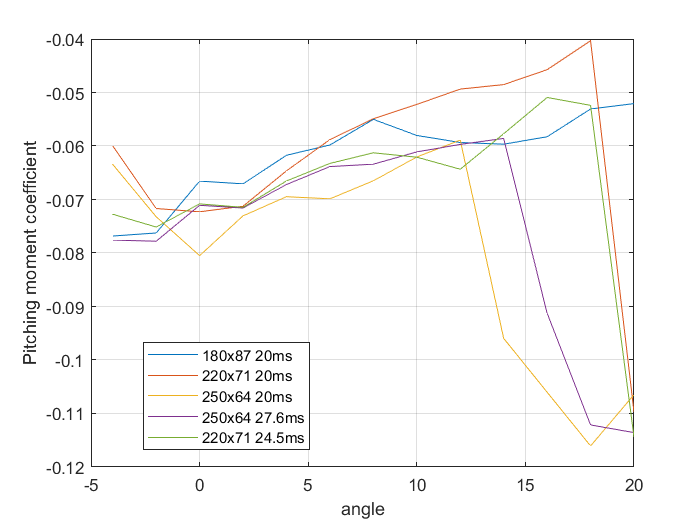



% To plot graph of Cm/alpha
plot (A0A, CM1, A0A, CM2,A0A, CM3,A0A, CM4,A0A, CM5)
xlabel ('angle')
ylabel ('Pitching moment coefficient')
legend ({'180x87 20ms', '220x71 20ms', '250x64 20ms', '250x64 27.6ms', '220x71 24.5ms'},'Location','best' )
grid on

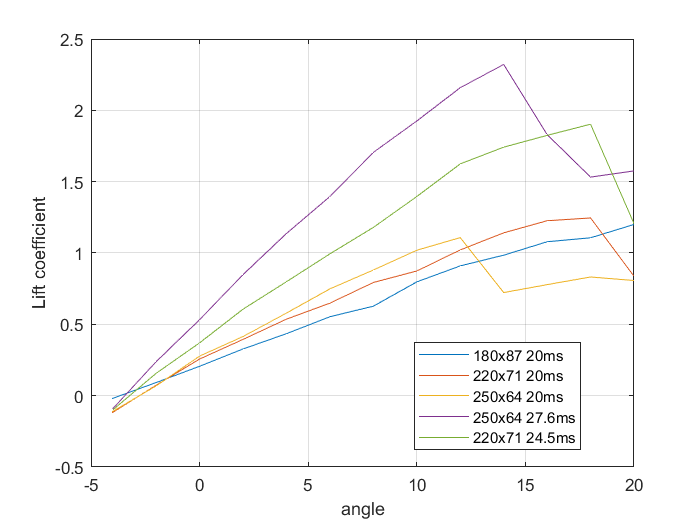


% To plot graph of Cm/alpha
plot (A0A, Cl1, A0A, Cl3,A0A, Cl5,A0A, Cl7,A0A, Cl8)
xlabel ('angle')
ylabel ('Lift coefficient')
legend ({'180x87 20ms', '220x71 20ms', '250x64 20ms', '250x64 27.6ms', '220x71 24.5ms'},'Location','best' )
grid on

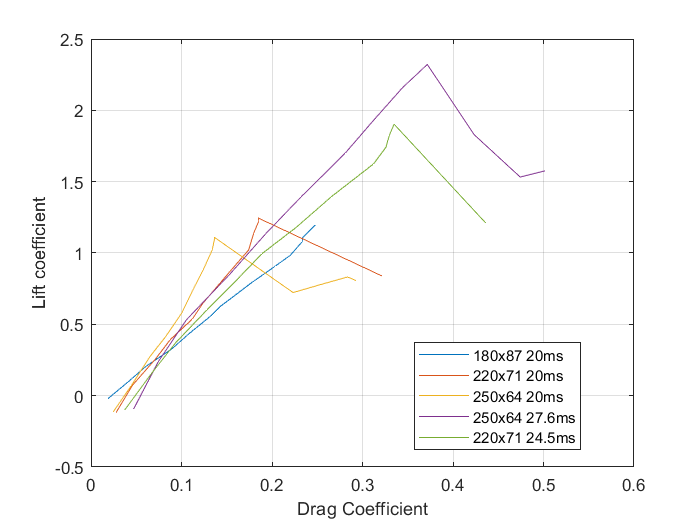


% To plot graph of CL/CD
plot (CD1, Cl1, CD3, Cl3,CD5, Cl5,CD7, Cl7,CD8, Cl8)
xlabel ('Drag Coefficient')
ylabel ('Lift coefficient')
legend ({'180x87 20ms', '220x71 20ms', '250x64 20ms', '250x64 27.6ms', '220x71 24.5ms'},'Location','best' )
grid on




% To calculate Reynolds number
                                                  
miu = (1.81*10^-5);        % dynamic viscosity of fluid                    

Rey = ((Ve *p .*Chords)/miu)     %  REYNOLDS NUMBER   

Rey = 	1.0e+05 *

    1.1776    0.9610    0.8663    1.1955    1.1773
